=== 第 1 次實驗 ===


1 0.005009
2 0.005009
3 0.005009


train data sse=0.012545, test data sse=0.012443
train data mse=0.000025, test data mse=0.000025
train data rmse=0.005009, test data rmse=0.004989
train data nmse=0.000489, test data nmse=0.000488


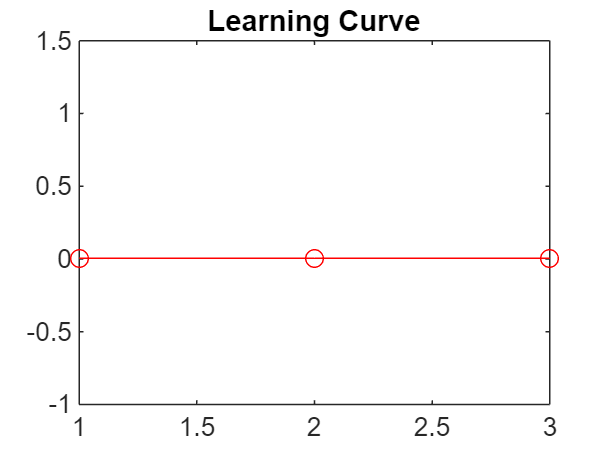

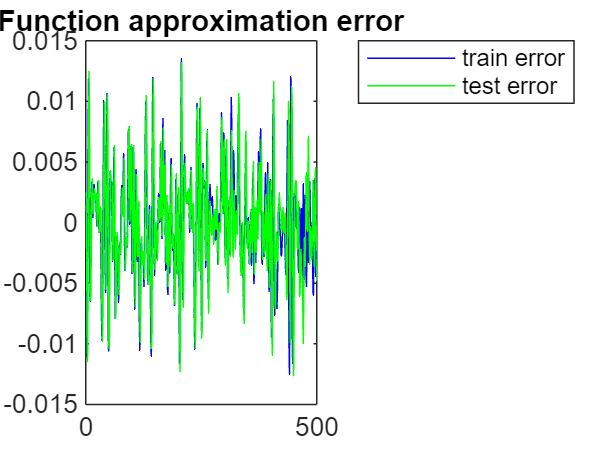

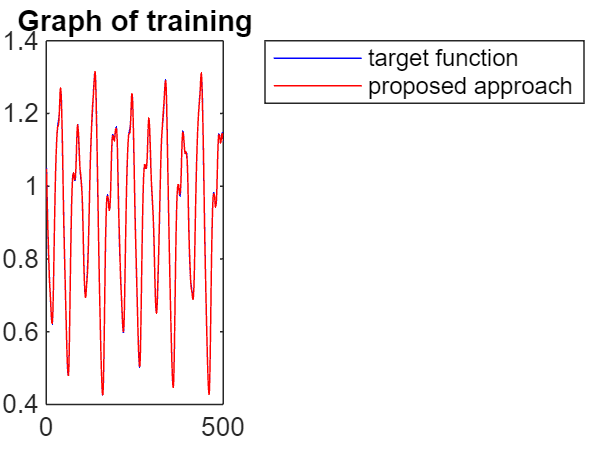

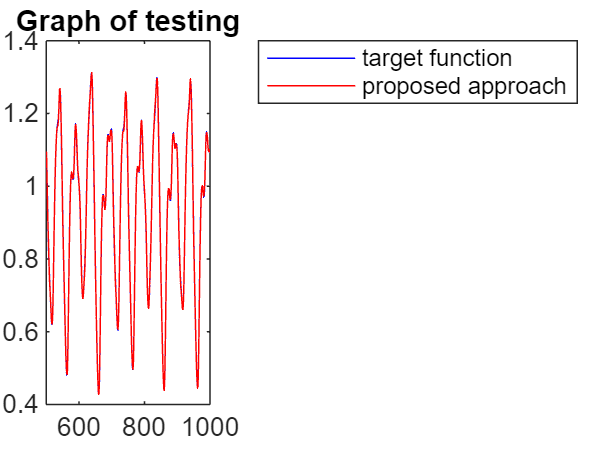

addpath(fullfile(pwd, 'Model'),fullfile(pwd, 'Model/Result'));
data = load("mgdata.dat");
Time = data(:,1);
X = data(:,2);

startIdx = 118;
numOfDataset = 1000;

T = zeros(numOfDataset, 1);
H = zeros(numOfDataset, 4);
Y = zeros(numOfDataset, 1);

%generate dataset
for i = startIdx:(startIdx+numOfDataset-1)
    H(i-startIdx+1,1) = X(i-18);
    H(i-startIdx+1,2) = X(i-12);
    H(i-startIdx+1,3) = X(i-6);
    H(i-startIdx+1,4) = X(i);
    Y(i-startIdx+1,1) = X(i+6);
    T(i-startIdx+1,1) = i+6;
end

%產生訓練資料
T_train = T(1:500,:);
H_train = H(1:500,:);
Y_train = Y(1:500,:);

%產生測試資料
T_test = T(501:1000,:);
H_test = H(501:1000,:);
Y_test = Y(501:1000,:);

%記錄跑幾次、最好、最差、平均值以及標準差
nRuns = 1;
finalRMSEs = zeros(nRuns,1);      % 每次最後 RMSE

%使用optimizer找出模型最佳參數
tIter = 3;
for r = 1:nRuns
    fprintf('=== 第 %d 次實驗 ===\n', r);
    [ifParm, cnsqParm, baseVarFuzzyN, lossAll] = optimizer(H_train, Y_train, tIter);
    finalRMSEs(r) = lossAll(end);        % 記錄最後 RMSE

    %使用approxiamtor預測資料
    Y_predict_train = approximator(H_train, ifParm, cnsqParm, baseVarFuzzyN);
    Y_predict_test = approximator(H_test, ifParm, cnsqParm, baseVarFuzzyN);

    %輸出圖形與損失值
    printLoss(Y_predict_train, Y_train, Y_predict_test, Y_test);
    model_plot([Y_predict_train,Y_train],[Y_predict_test,Y_test], lossAll );
end


% ====== 計算統計量 ======
bestVal = min(finalRMSEs);
worstVal= max(finalRMSEs);
meanVal = mean(finalRMSEs);
stdVal  = std(finalRMSEs);

% ====== 顯示統計結果 ======
fprintf('\n========= 統計結果 (共 %d 次) =========\n', nRuns);


========= 統計結果 (共 1 次) =========


fprintf('Best  RMSE: %.6f\n', bestVal);

Best  RMSE: 0.005009


fprintf('Worst RMSE: %.6f\n', worstVal);

Worst RMSE: 0.005009


fprintf('Mean  RMSE: %.6f\n', meanVal);

Mean  RMSE: 0.005009


fprintf('Std   RMSE: %.6f\n', stdVal);

Std   RMSE: 0.000000



rmpath(fullfile(pwd, 'Model'),fullfile(pwd, 'Model/Result'));